## 4.4. Call Python User Defined Functions From MATLAB

In this chapter, we will leverage a demo developed by a Finance colleague. In this example, he is responsible for building enterprise web predictive analytics that other business critical applications can connect to as a web service. It follows the same structure as the weather example in [chapter 2](about:blank<#_End-to-end_project_with%3E).

This web service is [**forecasting the price of cryptocurrencies**](https://www.mathworks.com/videos/integrating-python-with-matlab-1605793241650.html)**:** 

forecast.matlab.com/crypto.js?coin=ETH

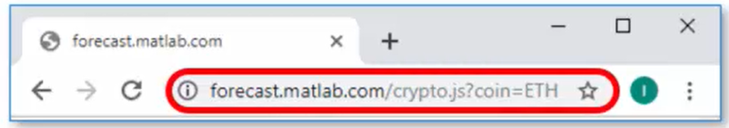

It returns data in the following form (JSON):

`[{``"Time"``:``"2022-01-21T12:00:00Z"``,``"predictedPrice"``:``2466.17``},`

`...`

`{``"Time"``:``"2022-01-21T17:00:00Z"``,``"predictedPrice"``:``2442.25``}]`

The first step is to develop an application that simply shows the historical price movement of a particular cryptocurrency:

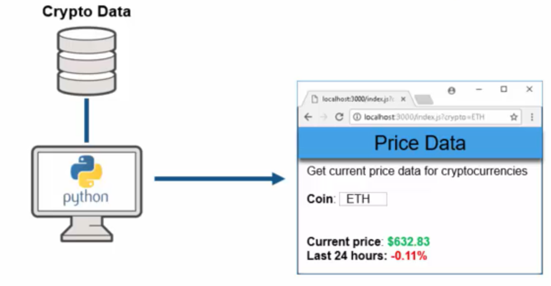

This allows you to monitor the evolution of the price over the last 24 hours and take decisions to buy or sell your crypto assets based on this. Then one day, you manager comes to you and says: 

*“Hey, I have an idea. If we had access to the predicted forward-looking data as opposed to the historical data, we could make additional profit beyond what we're currently making, even if the prediction is 100% accurate.“*

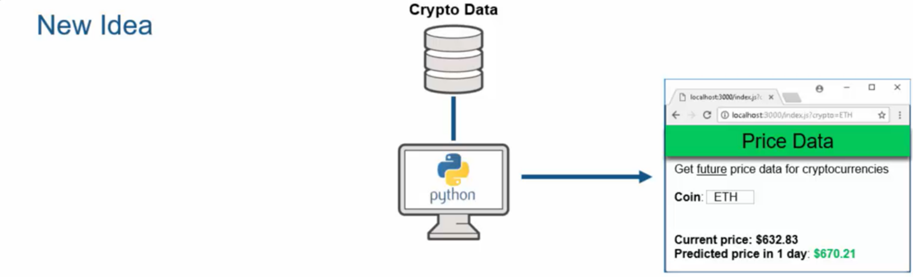

Let’s assume the organization has a few quants that have extensive MATLAB expertise. And they know exactly how to build out such predictive models that the business users are looking for.

However, before we can get to that, our first challenge is to call the Python data scraping libraries and pull that data directly into MATLAB. Our first task at hand: Parse the cryptocurrency URL that we are connecting to, and just get out the domain name. For that, we want to use this function that's contained within the Python standard libraries and use it from within MATLAB. In this case, we are going to call a package [`urllib`](https://docs.python.org/3/library/urllib.html). It contains a sub-module called `parse`, that contains in turn the function `urlparse`.

startDate = '2022-01-21T12:00:00Z';
stopDate = '2022-01-21T17:00:00Z';
url = "https://api.pro.coinbase.com/products/ETH-USD/candles?start="+startDate+"&end="+stopDate+"&granularity=60"
urlparts = py.urllib.parse.urlparse(url)
domain = urlparts.netloc

url = "https://api.pro.coinbase.com/products/ETH-USD/candles?start=2022-01-21T12:00:00Z&end=2022-01-21T17:00:00Z&granularity=60"

To avoid the unnecessary back and forth of intermediate data between MATLAB and Python, we write a [Python User Defined Module](https://www.mathworks.com/help/matlab/matlab_external/call-user-defined-custom-module.html), called `dataLib.py` with a few functions in it:

`dataLib.py` imports 1-minute bars from [Coinbase Pro](https://pro.coinbase.com/).  Note, the API does not fetch the first minute specified by the start date so the times span (start, stop]. To return data we are using a variety of data structures from Numpy arrays to lists and dictionaries, and even JSON.

This is how you would call this function from MATLAB.

Note: dataLib.py must be on Python's path

product = "ETH"

urlparts =   Python ParseResult with properties:

    fragment: [1×0 py.str]
    hostname: [1×20 py.str]
      netloc: [1×20 py.str]
      params: [1×0 py.str]
    password: [1×1 py.NoneType]
        path: [1×25 py.str]
        port: [1×1 py.NoneType]
       query: [1×66 py.str]
      scheme: [1×5 py.str]
    username: [1×1 py.NoneType]

    ParseResult(scheme='https', netloc='api.pro.coinbase.com', path='/products/ETH-USD/candles', params='', query='start=2022-01-21T12:00:00Z&end=2022-01-21T17:00:00Z&granularity=60', fragment='')


startDate = '2022-01-21T12:00:00Z';

domain =   Python str with no properties.

    api.pro.coinbase.com


stopDate = '2022-01-21T17:00:00Z';
jsonData = py.dataLib.getPriceData(product, startDate, stopDate);

If you want to add interactivity to your Live Script, you can add so called [Live Controls](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html). This is helpful to point other people to areas where you may want to change parameters or select things to do scenario analysis. 

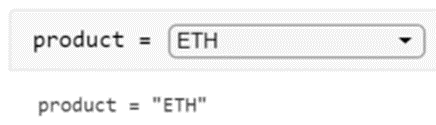

You can insert controls from the ribbon:

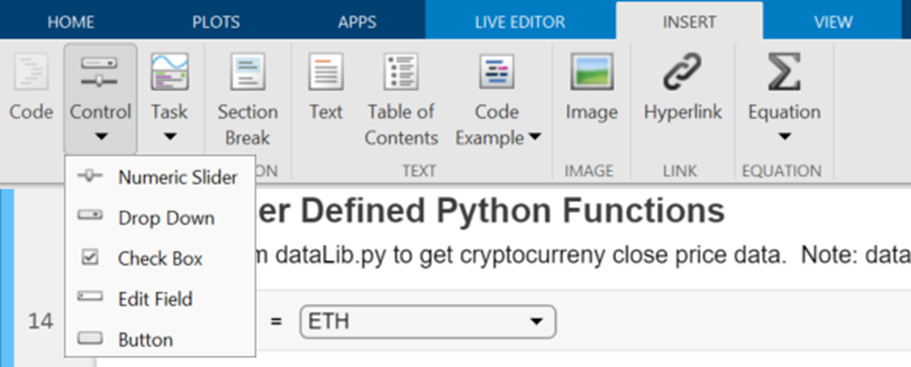

This is how you would parametrize the Live Control:

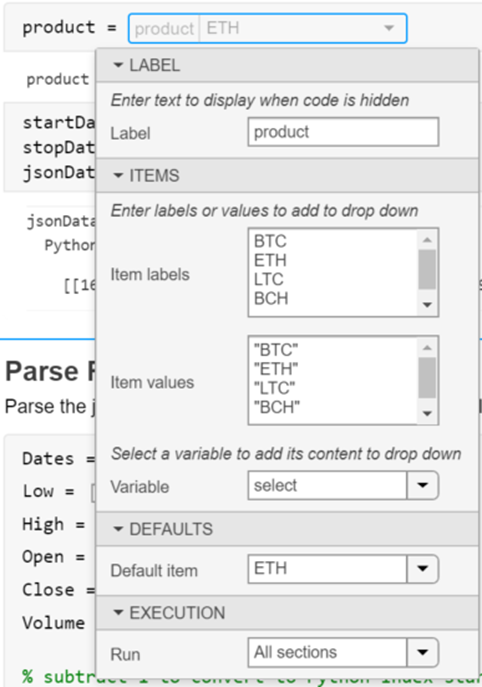

Another type of Live Control that is useful here are simple checkboxes to select the information we want to return from the `parseJson` function:

Dates = true;

product = "ETH"

Low = false;
High = false;
Open = false;
Close = true;
Volume = false;

% subtract 1 to convert to Python index starting at 0
selectedColumns = find([Dates Low High Open Close Volume])-1

Pay attention to the fact that we are subtracting 1 to the resulting array to adapt to Python indexing starting at 0.

% this function returns back two outputs as a tuple
data = py.dataLib.parseJson(jsonData, selectedColumns);

The last thing we will do in this part of the story is to convert the Python function outputs do MATLAB Data types (this will be covered in the last section of this chapter on mapping data between Python and MATLAB).

priceData = data{1}
columnNames = data{2}

Then we can cast over the Numpy array on the right-hand side by just using the double command:

priceData = double(priceData)

Likewise, we have a variety of commands for casting lists like string (or cell before R2022a):

columnNames = string(columnNames);

Once we have those data in MATLAB, we will convert it over to the MATLAB table, which is basically equivalent to Pandas data frames:

data = array2table(priceData, 'VariableNames', columnNames);

Like tables, timetable are built-in data constructs that appeared in MATLAB over the last couple of years to make our lives easy for doing simple types of tasks or even complex types of tasks. If I want to deal with time zones and convert the times – which are with respect to universal time zone – to a view of someone who is in New York, the command [datetime](https://www.mathworks.com/help/matlab/ref/datetime.html#d123e298898) allows us to do that conversion:

data.Date = datetime(data.Date, 'ConvertFrom', 'posixtime', 'TimeZone', 'America/New_York')

selectedColumns =      0     4


plot(data.Date, data.Close)

[**Reload Modified User-Defined Python Module**](https://www.mathworks.com/help/matlab/matlab_external/call-user-defined-custom-module.html#buuz303)

What if you’ve made modifications to the functions inside of your `dataLib` module? You call those again from MATLAB, but you don’t see any difference. It is because you need to reload the module:

mod = py.importlib.import_module('dataLib');

priceData =   Python ndarray:

   1.0e+09 *

    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000


py.importlib.reload(mod);

columnNames =   Python list with no properties.

    ['Date', 'Close']


You may need to unload the module first, by clearing the classes. This will delete all variables, scripts and classes in your MATLAB workspace.

clear classes 

priceData = 	1.0e+09 *

    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000
    1.6428    0.0000


If you're running Python out-of-process, another approach is to simply [terminate the process](https://www.mathworks.com/help/matlab/matlab_external/reload-python-interpreter.html).

data = 300×2 table
            Date            Close 
    ____________________    ______

    21-Jan-2022 12:00:00    2807.3
    21-Jan-2022 11:59:00    2810.8
    21-Jan-2022 11:58:00    2805.1
    21-Jan-2022 11:57:00    2807.1
    21-Jan-2022 11:56:00    2805.1
    21-Jan-2022 11:55:00    2802.8
    21-Jan-2022 11:54:00    2798.4
    21-Jan-2022 11:53:00    2798.3
    21-Jan-2022 11:52:00    2806.2
    21-Jan-2022 11:51:00    2805.4
    21-Jan-2022 11:50:00    2806.1
    21-Jan-2022 11:49:00    2801.2
    21-Jan-2022 11:48:00    2800.8
    21-Jan-2022 11:47:00      2803
    21-Jan-2022 11:46:00    2807.5
    21-Jan-2022 11:45:00      2813


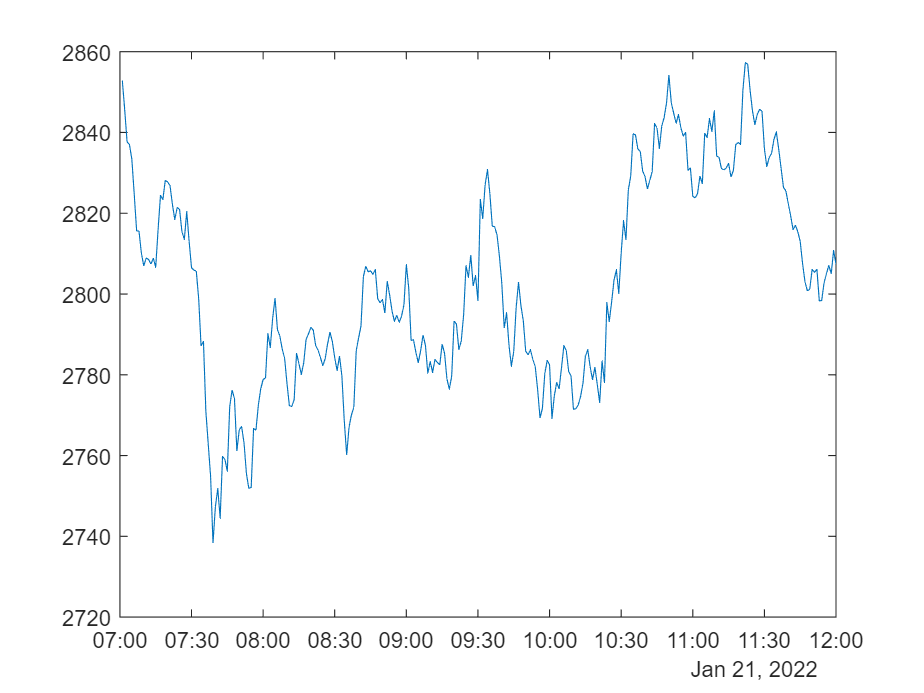

terminate(pyenv)